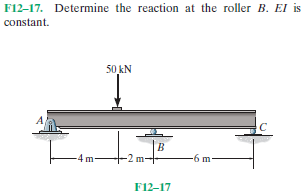

# beam

u = symunit;
b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('reaction', 'force', 'Rc', 12*u.m);
b = b.add('applied', 'force', -50*u.kN, 4*u.m);
b.L = 12*u.m;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{25\,x\,\left(396\,m^{2}-13\,x^{2}\right)}{162\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 4\,m\\ -\frac{25\,\left(x-6\,m\right)\,\left(41\,x^{2}-402\,x\,m+576\,m^{2}\right)}{162\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,6\,m\right]\\ \frac{125\,\left(x-6\,m\right)\,\left(x-12\,m\right)\,\left(x-18\,m\right)}{162\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{25\,\left(132\,m^{2}-13\,x^{2}\right)}{54\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 4\,m\\ -\frac{25\,\left(41\,x^{2}-432\,x\,m+996\,m^{2}\right)}{54\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,6\,m\right]\\ \frac{125\,\left(x^{2}-24\,x\,m+132\,m^{2}\right)}{54\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{325\,x}{27}\,\mathrm{kN} & \text{ if }x\leq 4\,m\\ -\frac{25\,\left(41\,x-216\,m\right)}{27}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,6\,m\right]\\ \frac{125\,\left(x-12\,m\right)}{27}\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{325}{27}\,\mathrm{kN} & \text{ if }x\leq 4\,m\\ -\frac{1025}{27}\,\mathrm{kN} & \text{ if }x\in \left(4\,m,6\,m\right]\\ \frac{125}{27}\,\mathrm{kN} & \text{ if }6\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

addvar(y);

# reactions

Ra = vpa(r.Ra, 4) %#ok

$$Ra = 12.04\,\mathrm{kN}$$

Rb = vpa(r.Rb, 4) %#ok

$$Rb = 42.59\,\mathrm{kN}$$

Rc = vpa(r.Rc, 3) %#ok

$$Rc = -4.63\,\mathrm{kN}$$

clear Ra Rb Rc;

# shear and moment diagram

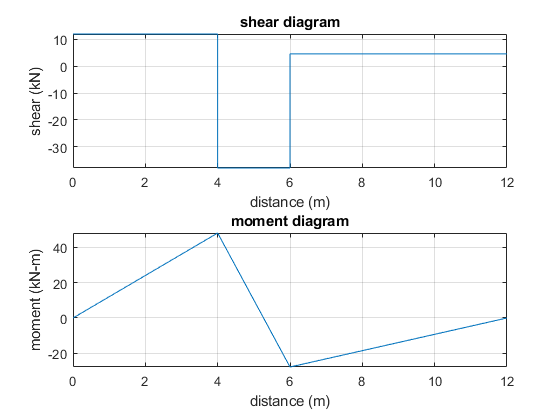

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});